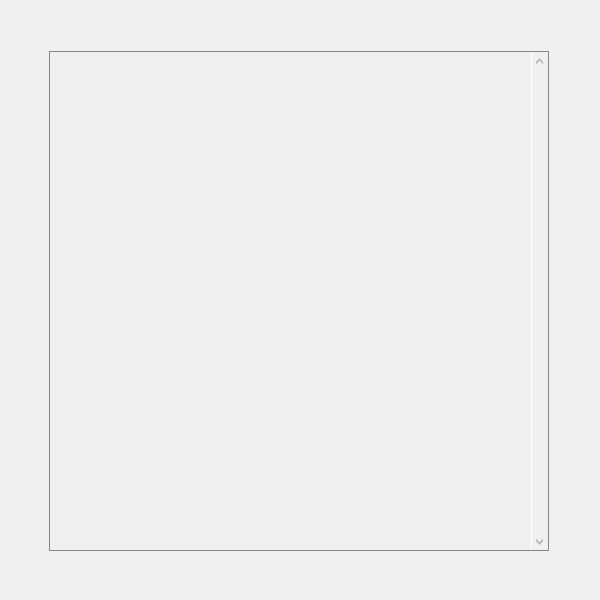

Error using readtable (line 245)
Unable to find or open '\info.txt'. Check the path and filename or file permissions.

Error in OpenIOI_NewSyst (line 29)
AcqInfoStream = readtable([FolderName filesep 'info.txt'],...

%Select experiment folder
FolderPath = uigetdir;
%Open raw .bin files
Binning = 1; %Bin IOI data
OpenIOI_NewSyst(FolderPath,Binning,3,0);

Signal preprocessing, including normalization (de-meaning and division by std) and bandpass filtering between 0.01 and 0.1 Hz.

%Extract green reflectance images
[Green,GreenROI] = extractImMatrix(FolderPath,'green',1);

Error using matlab.internal.language.isPartialMATArrayAccessEfficient
Unable to read MAT-file C:\Users\je_gu\GitHub\Connectivity-activation-mapping: not a binary MAT-file.


Error in matlab.io.matfile.Properties (line 58)
                obj.SupportsPartialAccess = matlab.internal.language.isPartialMATArrayAccessEfficient(obj.Source);

Error in 

f = matfile([FolderPath filesep 'Data_green.mat']).Freq; %Acquisition frequency
%Normalize and filter signal
Green = (Green-mean(Green))./std(Green);
Green = bandpass(Green,[0.01 0.1],f);
%Compute adjacency matrix
A = corr(Green);
%Compute FCS
I = fcs(A,'standard');
%Map on orignal image
FCSimage = remapROI(I,GreenROI);
figure;
imagesc(FCSimage);
colorbar;

